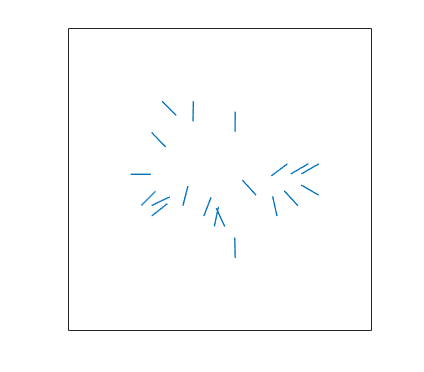

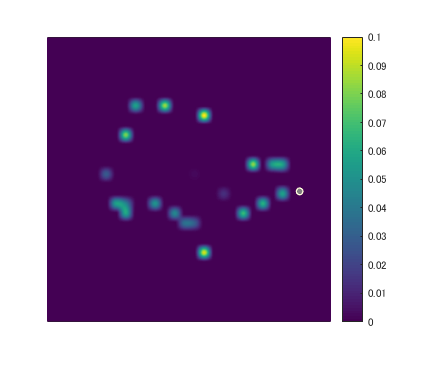

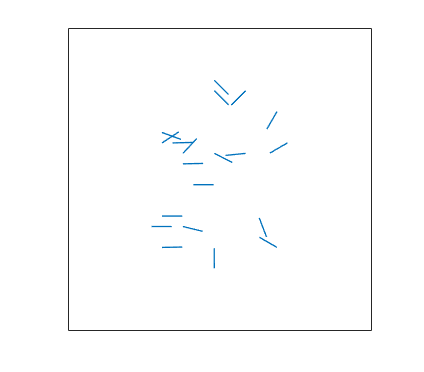

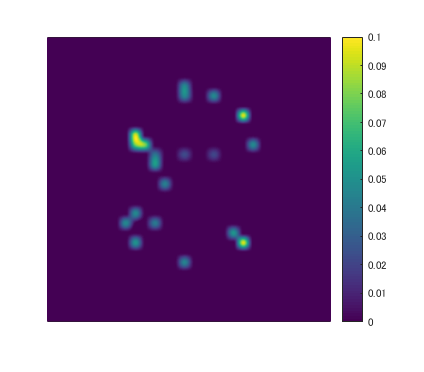

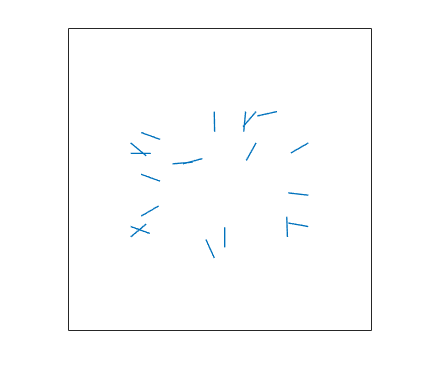

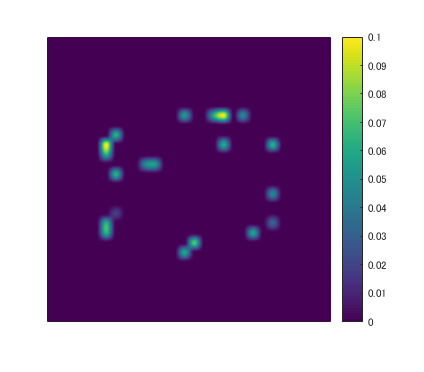

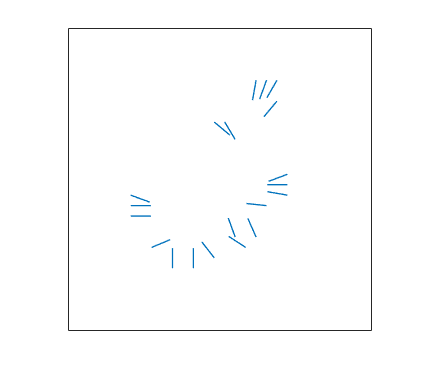

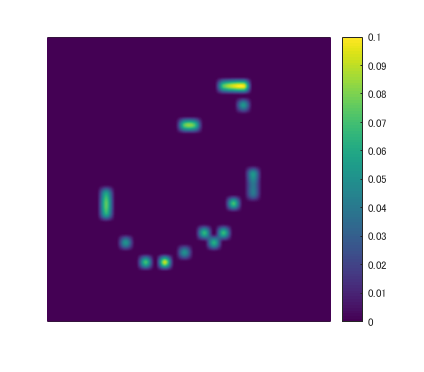

generateReport(mode="all")

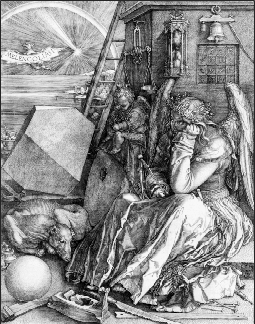

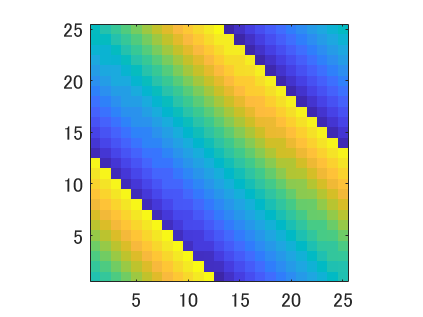

generateReport("./fig", mode="all", author="", title="", recurrent="on")

function fs = figFiles(rootDir, opt)

arguments
    rootDir (1, 1) string = ""
    opt.recurrent (1, 1) string {ismember(opt.recurrent, ["on", "off"])} = "off"
end

if strlength(rootDir) == 0
    [f, p] = uigetfile(MultiSelect="on");
    fs = string(strcat(p, f));
else
    fs = fun(rootDir, opt.recurrent);
end

    function fs = fun(rootDir, rec)
        fs = dir(rootDir);
        % omit files and directories whose name starts at "."
        I = cellfun(@(el) isempty(regexp(el, "^\.", 'once')), {fs.name});
        if ~any(I)
            fs = [];
            return;
        end
        fs = fs(I);
        if strcmp(rec, "off")
            I = cellfun(@(el) ~isempty(regexp(el, ".fig$", 'once')), {fs.name});
            fs = string(strcat(fs(1).folder, filesep, {fs(I).name}));
        end
        if strcmp(rec, "on")
            dirs = fs([fs.isdir]);
            fs = fun(fs(1).folder, "off");
            if isempty(dirs)
                return;
            end
            for d = dirs
                fs = [fs, fun(fullfile(d.folder, d.name), "on")];
            end
        end
    end

end

function svgfs = saveAsSVG(fs)

svgfs = [];

for f=fs
    h = openfig(f);
    [rootDir, fnm, ~] = fileparts(f);
    set(h, "Renderer", "painters");
    svgfs = [svgfs, fullfile(rootDir, sprintf("%s.%s", fnm, "svg"))];
    saveas(h, svgfs(end));
end

end

function generateHTMLReport(fs, outfnm, T, author)

arguments
    fs (1, :) string = []
    outfnm (1, 1) string = ""
    T (1, 1) string = ""
    author (1, 1) string = ""
end

if isempty(fs)
    return;
end

[rootDir, ~, ~] = fileparts(fs(1));

import mlreportgen.report.*

rpt = Report(fullfile(rootDir, outfnm), 'html-file');
titlepg = TitlePage;
titlepg.Title = T;
titlepg.Author = author;
add(rpt,titlepg);
add(rpt,TableOfContents);

for f=fs
    h = openfig(f);
    [~, fnm, ~] = fileparts(f);
    chap = Chapter(fnm);
    fig = Figure(h);
    cpt = get(gca, "title").String;
    if strlength(cpt) == 0; cpt = f; end
    fig.Snapshot.Caption = cpt;
    append(chap, fig);
    add(rpt,chap);
end

close(rpt);
end

function generatePPTReport(svgfs, outfnm, T, author)

arguments
    svgfs (1, :) string = []
    outfnm (1, 1) string = ""
    T (1, 1) string = ""
    author (1, 1) string = ""
end

if isempty(svgfs)
    return;
end

[rootDir, ~, ~] = fileparts(svgfs(1));

import mlreportgen.ppt.*

ppt = Presentation(fullfile(rootDir, strcat(outfnm, ".pptx")));
open(ppt);

titleSlide = add(ppt, 'Title Slide');
replace(titleSlide, "Title", T);
replace(titleSlide, "Subtitle", datestr(now));

for f=svgfs
    slide = add(ppt, "Title and Content");
    [~, fnm, ~] = fileparts(f);
    replace(slide, "Title", fnm);
    plane = Picture(f);
    replace(slide, "Content", plane);
end

close(ppt);
end

function generateReport(rootDir, opt)

arguments
    rootDir (1, 1) string = ""
    opt.mode (1, 1) string {mustBeMember(opt.mode, ["all", "html", "ppt"])} = "all"
    opt.author (1, 1) string = ""
    opt.title (1, 1) string = ""
    opt.recurrent (1, 1) string = "off"
end


fs = figFiles(rootDir, recurrent=opt.recurrent);
svgfs = saveAsSVG(fs);

outfnm = datestr(now, "yymmdd-HHMMSS");
title = opt.title;

if ~isempty(find(strcmp(opt.mode, ["all", "html"]), 1))
    generateHTMLReport(fs, outfnm, title, opt.author);
end

outfnm = datestr(now, "yymmdd-HHMMSS");
title = opt.title;

if ~isempty(find(strcmp(opt.mode, ["all", "ppt"]), 1))
    generatePPTReport(svgfs, outfnm, title, opt.author);
end

end